# Homogeneous Coordinates

Translations are **not** linear transformations and consequently cannot be accomplished via matrix multiplication using a $2\times 2$ matrix. To circumvent this problem we use ***homogeneous coordinates***. The homogeneous coordinates for a point ${\left(x_1 ,x_2 \right)}^T$ are ${\left(x_1 ,x_2 ,1\right)}^T \ldotp$

However, when the point represented by the homogeneous coordinates ${\left(x_1 ,x_2 ,1\right)}^T$ is plotted, only the $x_1$ and $x_2$ are taken into consideration. The 1 is ignored. This allows us to produced the translated coordinates for a figure by matrix multiplication. Suppose we want to translate the vector $c_1$ units horizontally and $c_2$ units vertically. In homogeneous coordinates the translated vector is ${\left(x_1 +c_1 ,x_2 +c_2 ,1\right)}^T \ldotp$ We need a matrix $M$ such that


$$M\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 +c_1 \\
x_2 +c_2 \\
1
\end{array}\right\rbrack$$


It is easy to verify that the matrix 


$$M=\left\lbrack \begin{array}{ccc}
1 & 0 & c_1 \\
0 & 1 & c_2 \\
0 & 0 & 1
\end{array}\right\rbrack$$


has the desired property.

# Example 7

We will apply a horizontal translation of $3$ units and a vertical translation of $-2$ units. The matrix that accomplishes that is $M=\left\lbrack \begin{array}{ccc}
1 & 0 & 3\\
0 & 1 & -2\\
0 & 0 & 1
\end{array}\right\rbrack \ldotp$ To apply the transformation to the square $S$, we will need to convert the square to homogeneous coordinates. This is done by adding a row of ones to the matrix $S$ so that the new matrix is $S=\left\lbrack \begin{array}{ccccc}
0 & 1 & 1 & 0 & 0\\
0 & 0 & 1 & 1 & 0\\
1 & 1 & 1 & 1 & 1
\end{array}\right\rbrack \ldotp$ We can plot the original square together with the translated version by executing the following commands:

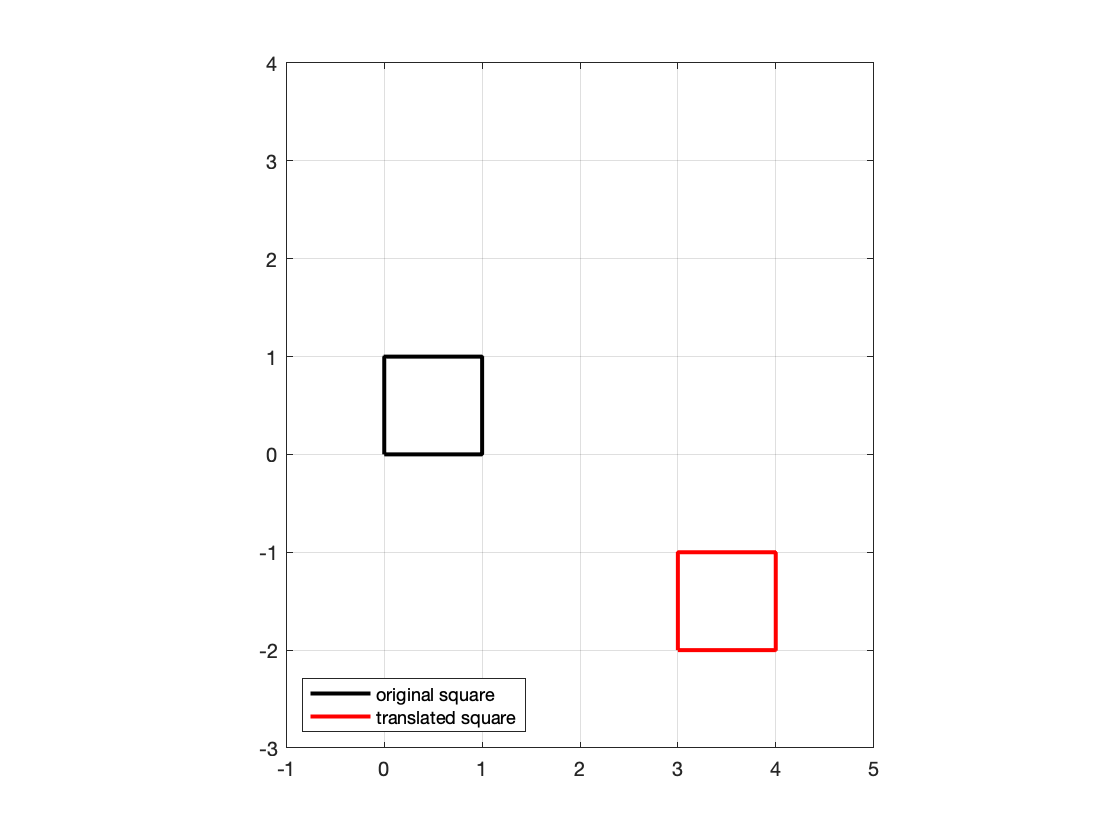

clf
S=[0,1,1,0,0;0,0,1,1,0;1,1,1,1,1]; % square in homogeneous coordinates
M=[1,0,3;0,1,-2;0,0,1]; % translation matrix
MS=M*S; % apply the translation to the square
plot(S(1,:),S(2,:),'k','linewidth',2); % plot the original square in black
hold on   % hold the figure
plot(MS(1,:),MS(2,:),'r','linewidth',2); % plot the translated square in red
legend('original square','translated square','location','southwest');
axis equal , axis([-1 ,5,-3,4]), grid on % adjust the axis
hold off

# Example 8

Consider the matrix $S$representing the original square in homogeneous coordinates. In the following script we translate the square horizontally using $c_1 =0\ldotp 2$ and $c_2 =0$ for $40$ times. We then translate the square vertically using $c_1 =0$ and $c_2 =0\ldotp 2$ and $40$ iterations. Run the script to see the resulting animation.

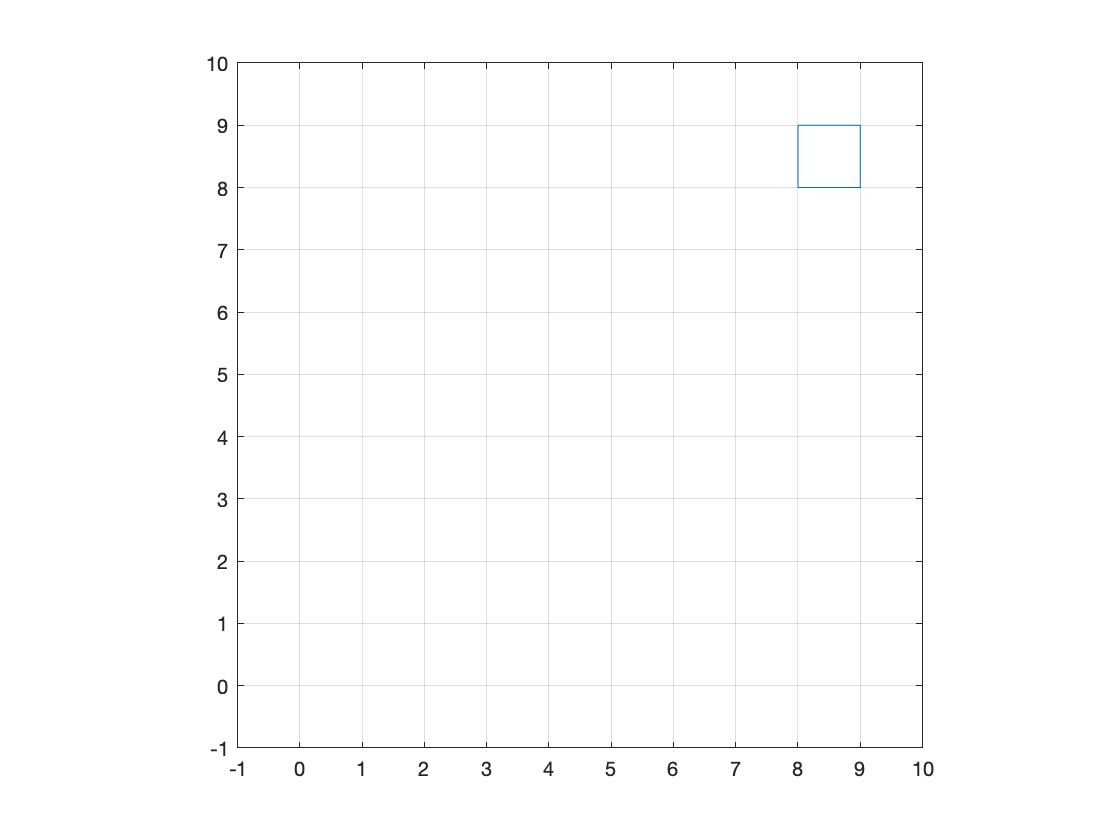

clf
S=[0,1,1,0,0;0,0,1,1,0;1,1,1,1,1]; % square in homogeneous coordinates
M1 = [1,0,0.2;0,1,0;0,0,1]; % first translation matrix
M2 = [1,0,0;0,1,0.2;0,0,1]; % the second translation matrix
p = plot(S(1,:),S(2,:)); % plot the original square
axis square , axis([-1,10,-1,10]) , grid on
for i = 1:40
  S = M1*S; % compute the translated square
  set(p,'xdata',S(1,:),'ydata',S(2,:)); % plot the translated square
  pause(0.2)
end
for i = 1:40
   S=M2*S; % compute the translated square
   set(p,'xdata',S(1,:),'ydata',S(2,:)); % plot the translated square
   pause(0.1)
end

# Reflection matrices

The reflection matrix about the line $L$ with direction the unit vector $\mathbf{u}$ is given by $
R=2\mathbf{u}\mathbf{u}^T-I$, where $I$ is the identity matrix.

For instance, to obtain the reflection matrix about the line at 45 degrees, we can take$\mathbf{u}=\left( \frac{\sqrt{2}}{2}, \frac{\sqrt{2}}{2}\right)^T$. Then  ${\mathbf{uu}}^T =\left\lbrack \begin{array}{cc}
\frac{1}{2} & \frac{1}{2}\\
\frac{1}{2} & \frac{1}{2}
\end{array}\right\rbrack$and $R=\left\lbrack \begin{array}{cc}
0 & 1\\
1 & 0
\end{array}\right\rbrack \ldotp$ (Note that this answer makes perfect sense, since the reflection of the vector $\mathbf{x}=(x_1,x_2)^T$ about the line at 45 degrees is the vector $(x_2, x_1)^T$.) In homogeneous coordinates, the reflection matrix becomes:


$$R=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


The other types of basic transformations (rotations, dilations) can all be adapted to homogeneous coordinates by augmenting the matrix by the row $\left(0,0,1\right)$ and the column ${\left(0,0,1\right)}^T \ldotp$ For instance, in homogeneous coordinates, the dilation matrix that dilates by a factor $\alpha$ becomes:


$$D=\left\lbrack \begin{array}{ccc}
\alpha  & 0 & 0\\
0 & \alpha  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \ldotp$$
